# Studio excercise 1

November 2013 Tomas McKelvey

This document can be used as an interactive workbook in Matlab Start Matlab and at the prompt type edit studio1.m the editor has a feature which divides the document into cells a new cell starts with a line starting with %%

## This is a new cell

You can let matlab run all the commands in the cell by typing Ctrl+Enter keys simultaneously. If you type Ctrl+Shift+Enter you will evaluate the current cell and then advance to next cell In each cell you can change the numerical values and evaluate In order to se the results of the change

## DFT of a sinusoidal signal

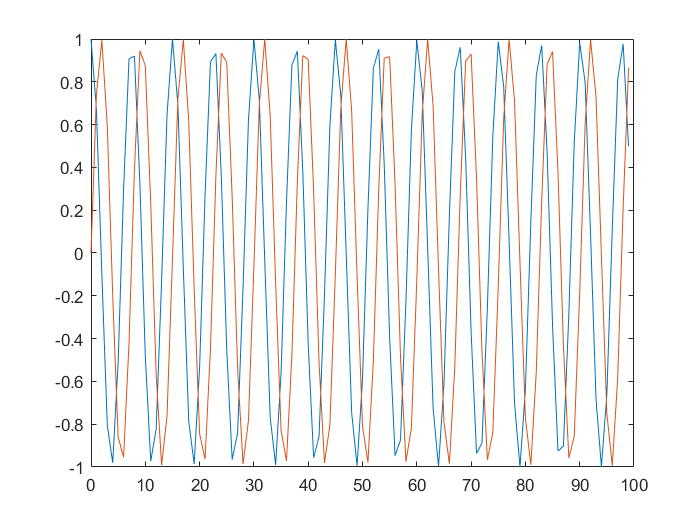

% Create a complex sinusoid of length 100 and frequency 0.133
% periods / sample

clf; % Clear graphs
N = 100;
f0 = 0.133;     % normalized frequency =>  f/fs = f*deltat

n = (0:N-1)'; % sample indices
x = exp(i*2*pi*f0*n); % create signal,   x = exp(i*2*pi*F0*n*deltat)   fs = 1/deltat  =>  f0=F0/fs
plot(n,[real(x) imag(x)] ); % plot real and imaginary parts of the complex signal

## Calculate the DFT of the signal

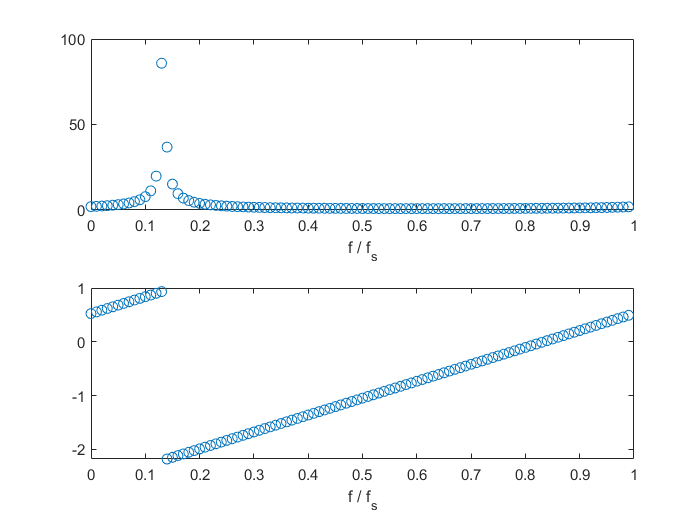

clf;
X = fft(x);
% frequency vector (relative to sampling frequency)
f = (0:N-1)'/N;     % 0 <= f/fs < 1

% Here we plot dots to show that the DFT really are discrete points
subplot(211)
plot(f, abs(X),'o'); % Amplitude
xlabel('f / f_s')
subplot(212)
plot(f, angle(X),'o'); % Phase
xlabel('f / f_s')

## Use zero padding to create more samples of the FT

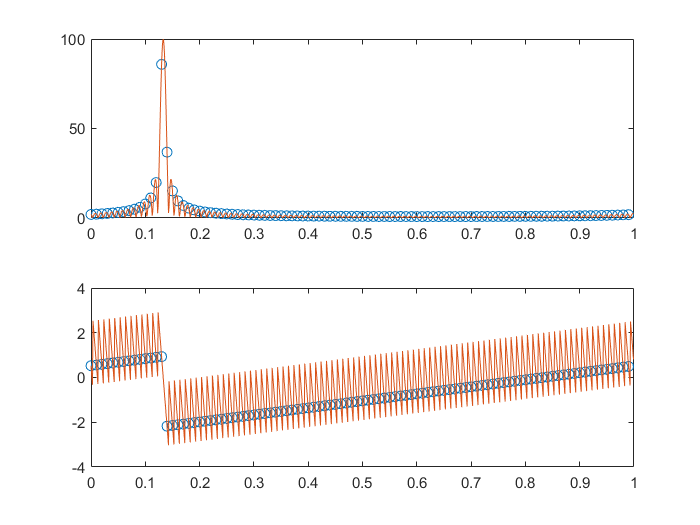

clf % clears the graphs

Z=1000;
L = N+Z;

fz = (0:L-1)'/L;
xz = [x ; zeros(Z,1)];
Xz = fft(xz);

subplot(211)
plot(f, abs(X),'o',fz,abs(Xz));
subplot(212)
plot(f, angle(X),'o', fz,angle(Xz));

## Compare with true answer

Recall the FT of a truncated complex sinusiod is the FT of the rectangular pulse shifted to the location of the sinusoid.

% if x(t) was continuous then X(w)=2*pi*dirac(w-w0)
% However, we are applying DTFT in xd(w)   
%       => Yd(w) = Hzoh(w) * Xd(w) = Hzoh(w) * 2pi/deltat*(dirac~(w-w0))
Xt = exp(-i*(N-1)/2*2*pi*(fz-f0)).*sin(N*2*pi*(fz-f0)/2)./sin(2*pi*(fz-f0)/2);

% Possibly we get a warning here if sin(2*pi*(fz-f0)/2)=0 (0/0).

% Calculate the norm of the error
norm(Xt-Xz)

ans = 1.3583e-12

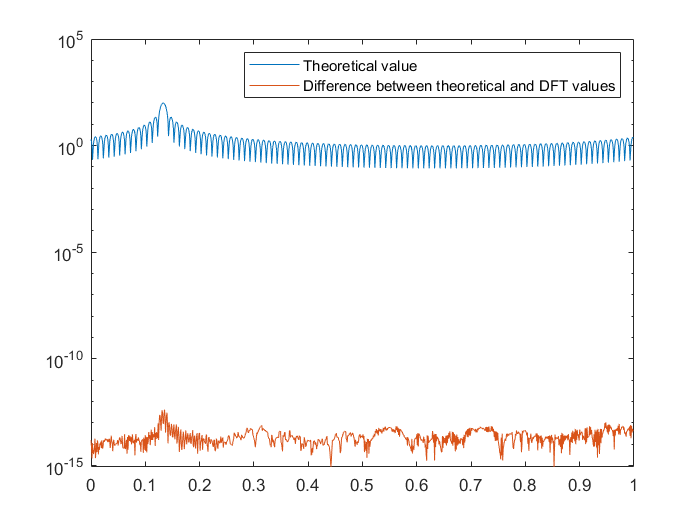


% The norm calulates the root mean square of a vector. If the norm is
% less than e.g. 1e-10, the vector (in this case) can be be regarded as zero. The non-zero value 
% is due to roundoff errors in the arithmetic.

% We can also plot the magnitude of y and the difference between them
% using a log scale to se that y and ydft are the same.
clf
semilogy(fz,abs([ Xt, Xt-Xz ]));
legend('Theoretical value', 'Difference between theoretical and DFT values');

% DFT clearly samples the FT of the windowed signal


% More things to test
% -> Use a negative frequency, Where does the negative frequencies show up in the plots?
% -> Use s real sinusoid i.e x = sin(2*pi*n); What symmetri do we obtain in
% phase and amplitude?

## Now try some other windows besides the rectangular

w = hanning(N);

Xh = fft(x.*w,N+Z); % This gives automatic zero padding with Z
                    % zeros
clf;		    
plot(fz,abs(Xz),'b',fz,abs(Xh),'g');

% Note that the max amplitude is lower. This is due to the window
% shape.

## Let's compare rectangular and hanning

plot(n,ones(N,1),'o',n ,w, '*');
legend('Rectangular', 'Hanning');

% Clearly the hanning window remove energy
% We can compensate by using a scale factor 

sf = N/sum(w);

## We see things a lot better in a log scale

semilogy(fz,abs(Xz),'b',fz,sf*abs(Xh),'g');
legend('Rectangular', 'Hanning');

% Main lobe is wider but sidelobes much smaller. This is due to a 
% smooth transition from zero as compared to the rectangular window.

## Now add a second sinusoid

x2 = x + 0.01 * exp(i*2*pi*0.3*n);

w = hanning(N);

Xh2 = fft(x2.*w,N+Z); % This gives automatic zero padding with Z zeros
Xz2 = fft(x2,N+Z); % This gives automatic zero padding with Z zeros

semilogy(fz,abs(Xz2),'b',fz,sf*abs(Xh2),'g');
legend('Rectangular', 'Hanning');

% Note that the second sinusoid is almost indestinguishable 
% with the rectangular window but is clear when using a hanning
% window. Why?

## Now add some noise to the signal

e = 0.1/sqrt(2)*(randn(N,1) + i*randn(N,1));

% What is the variance /standard deviation  ? Check it

std(e)

## % Add the noise to the signal

x2e = x2+e; 


Xh2e = fft(x2e.*w,N+Z); % This gives automatic zero padding with Z zeros
Xz2e = fft(x2e,N+Z); % This gives automatic zero padding with Z zeros

semilogy(fz,abs(Xz2e),'b',fz,sf*abs(Xh2e),'g');
legend('Rectangular', 'Hanning');

% The noise masks the weak sinusoidal signal.

## More things to test

-> Comapare rectangular window and hanning window when two sinusoids are nearby. Which window function enables us to detect two peaks? more windows exists. Se help hanning for examples of more windows

help hanning

## Use DFT to perform time domain convolution.

Lets use a simple averaging filter

Nh = 20;

h = [ones(Nh,1)]/Nh;

% Check the frequency response

H = fft(h,Nh+Z);
fz = (0:(Nh+Z-1))/(Nh+Z);
semilogy(fz,abs(H));

## Now filter the signal x through the averaging filter

y = conv(h,x);

% Matlab calculates the output for all possible non-zero samples 
% i.e.  for n=0,..,N+Nh-2

% Check if correct ...
length(y)

N+Nh-1

% Ok it is :-)

## Now do the convolution with DFT

We have three signals 1) the filter input x 2) the impulse response of the filter h 3) the output of the filter y and we need them all to have equal lenght and the length should be equal the longest of them. That is the length of y which is N+Nh-1. By zero padding x and h we can fix this

Ndft = N+Nh-1;
X = fft(x,Ndft); % DFT of x
H = fft(h,Ndft); % DFT of h
Y = H.*X;          % DFT of y
ydft = ifft(Y);    % y is IDFT of Y

% Check if the signals are equal
norm(y-ydft)

% The norm calulates the mean square error of a vector. If the norm is
% less than 1e-10 can be regarded as zero. The non-zero value 
% is due to roundoff errors in the arithmetic.

% We can also plot the magnitude of y and the difference between them
% using a log scale to se that y and ydft are the same.
semilogy(abs([y y-ydft]))

## For speed use FFT

DFT length need to be a power of 2

Nfft = 2^ceil(log2(N+Nh-1));
% and use FFT
yfft = ifft(fft(x,Nfft).*fft(h,Nfft));

plot(real(yfft))
% Now yfft has some extra zero at the end. Why?
% Compare
norm(y-yfft(1:N+Nh-1))
% Same again

## Fourier series and DFT

% Now assume x is a periodic function with period N
% and is 1 from n=0,..,L-1 and then zero for n=L,..,N-1

L = 7;
N = 50;

x = [ones(L,1); zeros(N-L,1)];
size(x) % check size...

% Since x is periodic it has a Fourier series representation
% The coefficents are simply given by the DFT

C = fft(x);

% Look at the coefficent
plot(abs(C),'o')

## Use DFT to calulate the circular convolution

Assume x is one period of a periodic signal We want to calulate the output (which is also periodic for a given impulse response h First do the calculation in the time domain Start by creating a quasi periodic signal

N=64; % period of the signa
x = randn(64,1); % Use a random input
xp = [x; x; x; x]; % repeat it 4 times
% Convolve with channel
yp = conv(h,xp);
plot(yp);
% Can you see the periodic output?
% Since the filter length 
size(h)
% is shorter than N=64
% already when the second period starts the output is periodic.
% pick this period 
y = yp(N+1:N*2);

## Now calulate this using DFT/FFT (circular convolution)

y_dft = ifft(fft(h,64).*fft(x));
% compare with the time domain filtering
norm(y-y_dft)
% Yes they are the same!

## Estimate the filter given inputs and outputs

Assume a signal x is periodic with period N. Filter x through a filter h with a finite impulse response After some samples the output will also become perfectly periodic. How long do we have to wait? Answer is the length of the filter

Now if the period time is larger than the length of the filter we can determine the filter from samples of the input and the output

Start with creating a signal where x is two periods long

xr = real(x); % This time we use a real signal
xp = real([xr; xr; xr; xr;]); 
% Filter xp through h
yp = conv(xp,h);
plot([xp yp(1:4*N,1)])
legend('input', 'output');
% We see that the output for the three last periods are identical

## We can use the DFT to calculate the Fourier series coefficents

for the inputs and the outputs.

Xr = fft(xr);
Yr = fft(yp(N+1:2*N));
% If Xr for all frequencies are non-zero, the DTFT of the filter at the frequencies 
% k/N, k=0,..,N-1 is of course
Hr = Yr./Xr;
hr = ifft(Hr);

clf
plot(hr,'x'); 
hold on
plot(h,'o');
hold off

% We note that hr and h contain the same impulse response. Hence we have
% found the impulse response of the filter by using DFT and the fact
% that a the output of a FIR filter with a periodic input  becocomes
% periodic after Nh samples (i.e. the length of the FIR filter.

## ALiasing

% The time interval with small enough steps 
% so the plots of functions continous
t=0:0.00001:1;      
% Frequency of first signal
f1=4;               
fs=10;              % Sampling frequency
s1=cos(2*pi*f1*t);  % First signal
ts=0:(1/fs):1;      % Sampling times
s1_sampled=cos(2*pi*f1*ts); % Sampled version of first signal
                    % plot the signal and its sampled version
figure
plot(t,s1,ts,s1_sampled,'ro')

f2=6;               % Frequency of second signal to avoid aliasing
                    % The frequency should be below 5 (= fs/2)
s2=cos(2*pi*f2*t);  % Second signal
s2_sampled=cos(2*pi*f2*ts); % Sampled version of second signal
hold 
plot(t,s2,'k')      % Overlay the second signal on previous plot
hold off

N=2^12;             % Choose number of samples of DTFT. 
                    % FFT function likes powers of two!
f=(0:N-1)'/N;       % Relative frequency
                    % Plot frequncy 
figure              
subplot(211)
plot(f,abs(fft(s1_sampled,N)));
subplot(212)
plot(f,abs(fft(s2_sampled,N)));